###  Plotting mean and standard error of G1 and G2 of all dataset

% CBD: Rat10, Rat212
% VEH: Rat210, Rat213

# **CBD ( Rat10, Rat212 )**

% Calculate mean for each row and for even and odd indices separately
Rat10_CBD_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_CSWR_Peak\Rat10(CBD)-cswr_2Gen.mat").results

Rat10_CBD_CSWR = 1×7 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_Ripple_Peak\Rat10(CBD)-Ripp_2Gen.mat").results

Rat10_CBD_Ripple = 1×696 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_SW_Peak\Rat10(CBD)-SW_2Gen.mat").results

Rat10_CBD_SW = 1×59 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_SWR_Peak\Rat10(CBD)-SWR_2Gen.mat").results

Rat10_CBD_SWR = 1×105 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Rat212_CBD_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_CSWR_Peak\Rat212(CBD)-cswr_2Gen.mat").results

Rat212_CBD_CSWR = 1×93 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_Ripple_Peak\Rat212(CBD)-Ripp_2Gen.mat").results

Rat212_CBD_Ripple = 1×89 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_SW_Peak\Rat212(CBD)-SW_2Gen.mat").results

Rat212_CBD_SW = 1×230 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_SWR_Peak\Rat212(CBD)-SWR_2Gen.mat").results

Rat212_CBD_SWR = 1×213 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Channels = 32;
Generators = 2;
%................................
%Rat10_CSWR
Events = numel(Rat10_CBD_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat10_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat10_CBD_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat10_Ripple
Events = numel(Rat10_CBD_Ripple); 
Generators_Rat10_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat10_SW
Events = numel(Rat10_CBD_SW); 
Generators_Rat10_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat10_SWR
Events = numel(Rat10_CBD_SWR); 
Generators_Rat10_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_SWR(i, :, :) = reshapedField;
end
%...............................
%Rat212_CSWR
Events = numel(Rat212_CBD_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat212_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat212_CBD_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField,Channels, Generators);
    Generators_Rat212_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat212_Ripple
Events = numel(Rat212_CBD_Ripple);
Generators_Rat212_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat212_SW
Events = numel(Rat212_CBD_SW); 
Generators_Rat212_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat212_SWR
Events = numel(Rat212_CBD_SWR); 
Generators_Rat212_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_SWR(i, :, :) = reshapedField;
end

# **VEH ( Rat210, Rat213 )**

% Calculate mean for each row and for even and odd indices separately
Rat210_VEH_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_CSWR_Peak\Rat210(VEH)-cswr_2Gen.mat").results

Rat210_VEH_CSWR = 1×71 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_Ripple_Peak\Rat210(VEH)-Ripp_2Gen.mat").results

Rat210_VEH_Ripple = 1×328 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_SW_Peak\Rat210(VEH)-SW_2Gen.mat").results

Rat210_VEH_SW = 1×191 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_SWR_Peak\Rat210(VEH)-SWR_2Gen.mat").results

Rat210_VEH_SWR = 1×281 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Rat213_VEH_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_CSWR_Peak\Rat213(VEH)-cswr_2Gen.mat").results

Rat213_VEH_CSWR = 1×82 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_Ripple_Peak\Rat213(VEH)-Ripp_2Gen.mat").results

Rat213_VEH_Ripple = 1×51 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_SW_Peak\Rat213(VEH)-SW_2Gen.mat").results

Rat213_VEH_SW = 1×390 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_SWR_Peak\Rat213(VEH)-SWR_2Gen.mat").results

Rat213_VEH_SWR = 1×116 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Events = numel(Rat210_VEH_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat210_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat210_VEH_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat210_Ripple
Events = numel(Rat210_VEH_Ripple); 
Generators_Rat210_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat210_SW
Events = numel(Rat210_VEH_SW); 
Generators_Rat210_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat210_SWR
Events = numel(Rat210_VEH_SWR); 
Generators_Rat210_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_SWR(i, :, :) = reshapedField;
end
%...............................
%Rat213_CSWR
Events = numel(Rat213_VEH_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat213_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat213_VEH_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField,Channels, Generators);
    Generators_Rat213_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat213_Ripple
Events = numel(Rat213_VEH_Ripple);
Generators_Rat213_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat213_SW
Events = numel(Rat213_VEH_SW); 
Generators_Rat213_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat213_SWR
Events = numel(Rat213_VEH_SWR); 
Generators_Rat213_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_SWR(i, :, :) = reshapedField;
end

# Plots

Average_CBD_CSWR= squeeze(mean(Generators_Rat10_CSWR,1)+mean(Generators_Rat212_CSWR,1))/2

Average_CBD_CSWR =     0.1486    0.0120
    0.1519    0.0422
    0.1510    0.0460
    0.1683    0.0201
    0.1756    0.0137
    0.1736    0.0260
    0.1427    0.1541
    0.1687    0.0408
    0.1912   -0.0863
    0.2478   -0.3914


Average_CBD_Ripple= squeeze(mean(Generators_Rat10_Ripple,1)+mean(Generators_Rat212_Ripple,1))/2

Average_CBD_Ripple =     0.1715    0.4598
    0.1722    0.4392
    0.1739    0.4507
    0.1814    0.4543
    0.1846    0.4528
    0.1822    0.4509
    0.1754    0.4317
    0.1747    0.4041
    0.1818    0.2839
    0.2123    0.0653


Average_CBD_SW= squeeze(mean(Generators_Rat10_SW,1)+mean(Generators_Rat212_SW,1))/2

Average_CBD_SW =     0.1526   -0.0460
    0.1519    0.0237
    0.1543    0.0254
    0.1623    0.0526
    0.1672    0.1069
    0.1671    0.2199
    0.1529    0.4247
    0.1599    0.4879
    0.1613    0.5673
    0.1813    0.3243


Average_CBD_SWR= squeeze(mean(Generators_Rat10_SWR,1)+mean(Generators_Rat212_SWR,1))/2

Average_CBD_SWR =     0.1904    1.2846
    0.1968    1.3441
    0.2016    1.3452
    0.2125    1.3426
    0.2182    1.3209
    0.2172    1.2964
    0.2131    0.9724
    0.2072    1.1443
    0.2167    0.7696
    0.2565   -0.1064



% Mean of VEH
Average_VEH_CSWR=squeeze(mean(Generators_Rat210_CSWR,1)+mean(Generators_Rat213_CSWR,1))/2

Average_VEH_CSWR =     0.0042 -130.7799
    0.0007 -137.3056
   -0.0018 -143.2982
   -0.0025 -146.7941
   -0.0060 -151.6219
   -0.0089 -153.7712
    0.0014 -157.3293
    0.0509 -185.8609
    0.1675 -257.2331
    0.2696 -294.0398


Average_VEH_Ripple=squeeze(mean(Generators_Rat210_Ripple,1)+mean(Generators_Rat213_Ripple,1))/2

Average_VEH_Ripple =     0.0950   -0.5333
    0.0902   -0.3859
    0.0811   -0.3003
    0.0792   -0.1678
    0.0758   -0.0235
    0.0815    0.0387
    0.1059   -0.1106
    0.1685   -0.5605
    0.2869   -1.4986
    0.3874   -2.3105


Average_VEH_SW=squeeze(mean(Generators_Rat210_SW,1)+mean(Generators_Rat213_SW,1))/2

Average_VEH_SW =     0.2422    0.6242
    0.2369    0.5896
    0.2302    0.5904
    0.2281    0.5808
    0.2257    0.5982
    0.2271    0.6408
    0.2358    0.7424
    0.2556    0.8271
    0.3023    0.9327
    0.3434    1.3263


Average_VEH_SWR=squeeze(mean(Generators_Rat210_SWR,1)+mean(Generators_Rat213_SWR,1))/2

Average_VEH_SWR =     0.0900    0.1454
    0.0896    0.2789
    0.0883    0.3566
    0.0890    0.3571
    0.0894    0.4733
    0.0919    0.2487
    0.1048   -0.4209
    0.1497   -2.2460
    0.2590   -6.1551
    0.3567  -10.6011


%.....................
% Standard Error of the mean - CBD
Sem_CBD_CSWR = squeeze(std(cat(1,Generators_Rat10_CSWR,Generators_Rat212_CSWR), 1) / sqrt(size(cat(1,Generators_Rat10_CSWR,Generators_Rat212_CSWR), 1)));
Sem_CBD_Ripple = squeeze(std(cat(1,Generators_Rat10_Ripple,Generators_Rat212_Ripple),1) / sqrt(size(cat(1,Generators_Rat10_Ripple,Generators_Rat212_Ripple), 1)));
Sem_CBD_SW = squeeze(std(cat(1,Generators_Rat10_SW,Generators_Rat212_SW),1) / sqrt(size(cat(1,Generators_Rat10_SW,Generators_Rat212_SW), 1)));
Sem_CBD_SWR = squeeze(std(cat(1,Generators_Rat10_SWR,Generators_Rat212_SWR),1) / sqrt(size(cat(1,Generators_Rat10_SWR,Generators_Rat212_SWR), 1)));
% Standard Error of the mean - VEH
Sem_VEH_CSWR = squeeze(std(cat(1,Generators_Rat210_CSWR,Generators_Rat213_CSWR), 1) / sqrt(size(cat(1,Generators_Rat210_CSWR,Generators_Rat213_CSWR), 1)));
Sem_VEH_Ripple = squeeze(std(cat(1,Generators_Rat210_Ripple,Generators_Rat213_Ripple),1) / sqrt(size(cat(1,Generators_Rat210_Ripple,Generators_Rat213_Ripple), 1)));
Sem_VEH_SW = squeeze(std(cat(1,Generators_Rat210_SW,Generators_Rat213_SW),1) / sqrt(size(cat(1,Generators_Rat210_SW,Generators_Rat213_SW), 1)));
Sem_VEH_SWR = squeeze(std(cat(1,Generators_Rat210_SWR,Generators_Rat213_SWR),1) / sqrt(size(cat(1,Generators_Rat210_SWR,Generators_Rat213_SWR), 1)));
%..........................................
%G1
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,1),timevect,  Sem_CBD_CSWR(:,1)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,1),timevect,Sem_CBD_Ripple(:,1)','c','alpha', ...
     Average_CBD_SW(:,1),timevect,    Sem_CBD_SW(:,1)','r','alpha',  ...
     Average_CBD_SWR(:,1),timevect,   Sem_CBD_SWR(:,1)','b','alpha',  ...
     Average_VEH_CSWR(:,1),timevect,  Sem_VEH_CSWR(:,1)' ,'g','alpha', ...
     Average_VEH_Ripple(:,1),timevect,Sem_VEH_Ripple(:,1)','m','alpha',...
     Average_VEH_SW(:,1),timevect,    Sem_VEH_SW(:,1)','y','alpha',  ...
     Average_VEH_SWR(:,1),timevect,   Sem_VEH_SWR(:,1)','b','alpha', 'orientation', 'horiz')

hl_g1 =   8×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


hp_g1 =   8×1 Patch array:

  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch


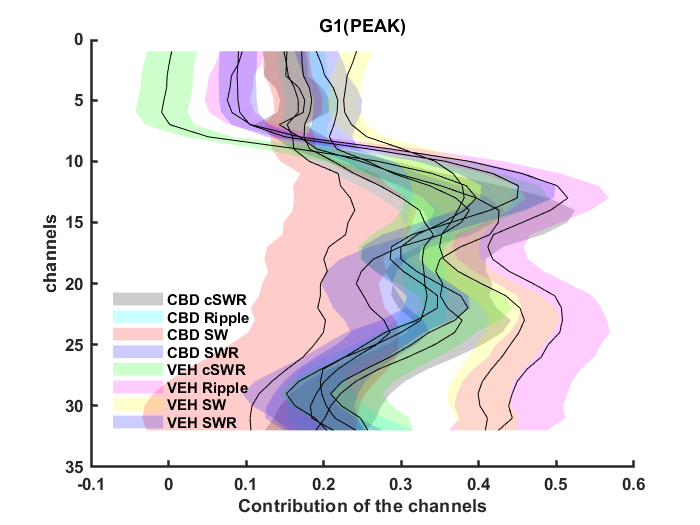


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%.......................................
%G2
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Average_CBD_CSWR(:,2),timevect,  Sem_CBD_CSWR(:,2) ,'--k', 'alpha',...
    Average_CBD_Ripple(:,2),timevect,Sem_CBD_Ripple(:,2),'--c','alpha',...
    Average_CBD_SW(:,2),timevect,    Sem_CBD_SW(:,2),'--r','alpha', ...
    Average_CBD_SWR(:,2),timevect,   Sem_CBD_SWR(:,2),'--b','alpha', ...
    Average_VEH_CSWR(:,2),timevect,  Sem_VEH_CSWR(:,2) ,'k','alpha',...
    Average_VEH_Ripple(:,2),timevect,Sem_VEH_Ripple(:,2),'c','alpha',...
    Average_VEH_SW(:,2),timevect,    Sem_VEH_SW(:,2),'r','alpha', ...
    Average_VEH_SWR(:,2),timevect,   Sem_VEH_SWR(:,2),'b','alpha','orientation', 'horiz')

hl_g2 =   8×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


hp_g2 =   8×1 Patch array:

  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch


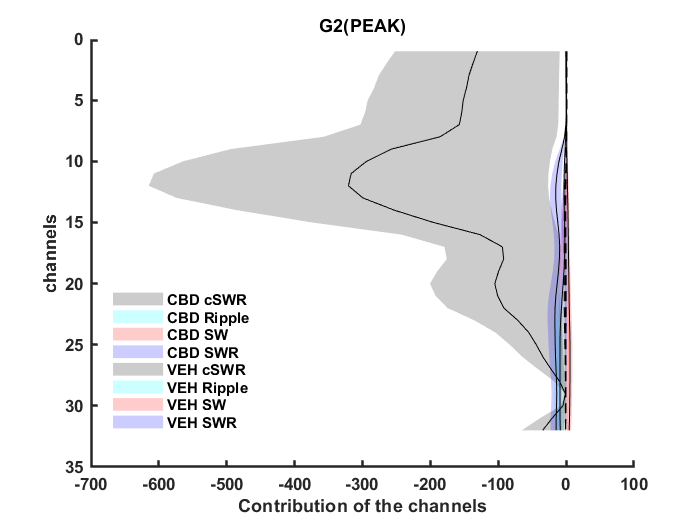


% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g2,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g2,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([-10 10])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%G1
figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,1),timevect, Sem_CBD_CSWR(:,1),'horizontal', 'k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,1),timevect, Sem_CBD_Ripple(:,1),'horizontal', 'y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,1),timevect, Sem_CBD_SW(:,1),'horizontal', 'b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,1),timevect, Sem_CBD_SWR(:,1),'horizontal', 'r','LineWidth', 0.5);

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,1),timevect, Sem_VEH_CSWR(:,1),'horizontal', 'g','LineWidth', 0.5);
errorbar( Average_VEH_Ripple(:,1),timevect, Sem_VEH_Ripple(:,1),'horizontal', 'c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,1),timevect, Sem_VEH_SW(:,1),'horizontal', 'm','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,1),timevect, Sem_VEH_SWR(:,1),'horizontal', 'k','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-1 1])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')
%................
%G2
figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,2),timevect, Sem_CBD_CSWR(:,2),'horizontal', 'k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,2),timevect, Sem_CBD_Ripple(:,2),'horizontal', 'y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,2),timevect, Sem_CBD_SW(:,2),'horizontal', 'b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,2),timevect, Sem_CBD_SWR(:,2),'horizontal', 'r','LineWidth', 0.5);

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,2),timevect, Sem_VEH_CSWR(:,2),'horizontal', 'g','LineWidth', 0.5);
errorbar( Average_VEH_Ripple(:,2),timevect, Sem_VEH_Ripple(:,2),'horizontal', 'c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,2),timevect, Sem_VEH_SW(:,2),'horizontal', 'm','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,2),timevect, Sem_VEH_SWR(:,2),'horizontal', 'k','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

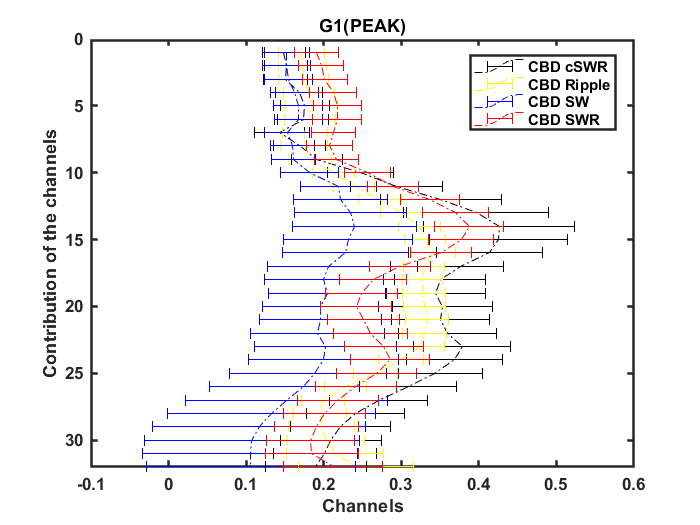

%G1_CBD
figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,1),timevect, Sem_CBD_CSWR(:,1),'horizontal', '-.k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,1),timevect, Sem_CBD_Ripple(:,1),'horizontal', '-.y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,1),timevect, Sem_CBD_SW(:,1),'horizontal', '-.b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,1),timevect, Sem_CBD_SWR(:,1),'horizontal', '-.r','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
xlabel('Channels')
ylim([0 32])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

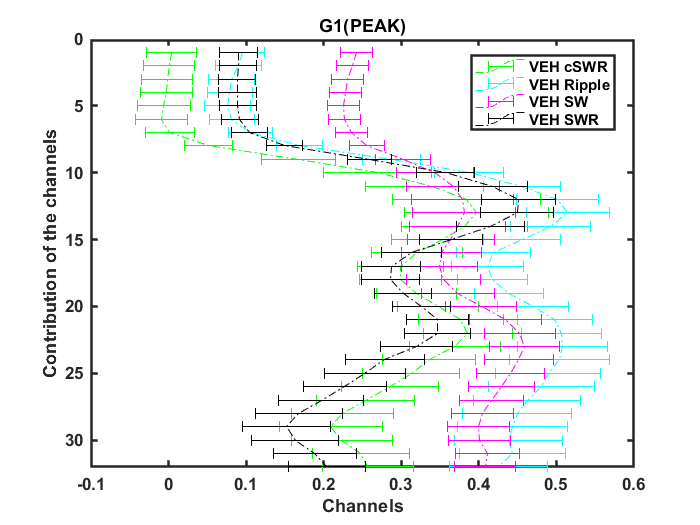

%................
%G1_VEH
figure;

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,1),timevect, Sem_VEH_CSWR(:,1),'horizontal', '-.g','LineWidth', 0.5);
hold on;
errorbar( Average_VEH_Ripple(:,1),timevect, Sem_VEH_Ripple(:,1),'horizontal', '-.c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,1),timevect, Sem_VEH_SW(:,1),'horizontal', '-.m','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,1),timevect, Sem_VEH_SWR(:,1),'horizontal', '-.k','LineWidth', 0.5);

legend('VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

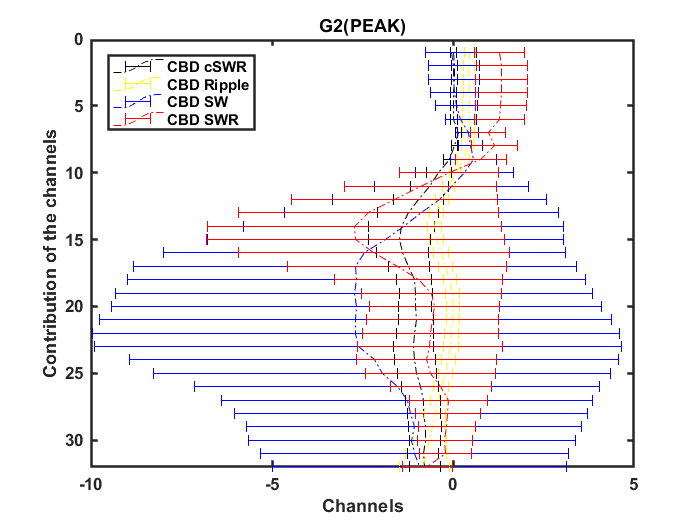

%..............
%G2_CBD
figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,2),timevect, Sem_CBD_CSWR(:,2),'horizontal', '-.k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,2),timevect, Sem_CBD_Ripple(:,2),'horizontal', '-.y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,2),timevect, Sem_CBD_SW(:,2),'horizontal', '-.b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,2),timevect, Sem_CBD_SWR(:,2),'horizontal', '-.r','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
xlabel('Channels')
ylim([0 32])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

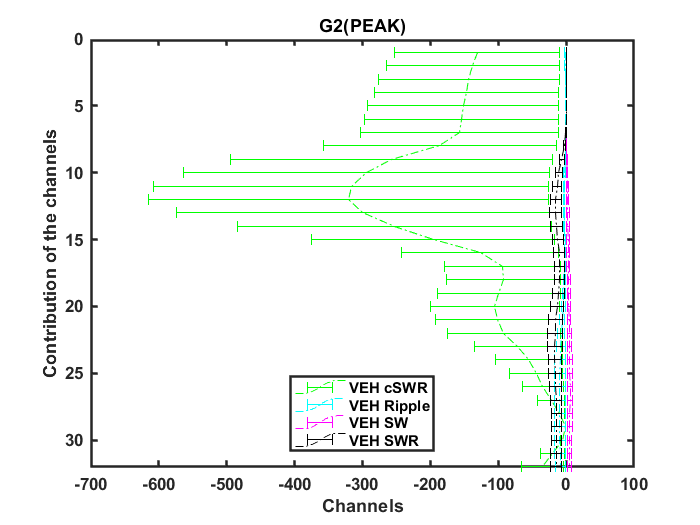

%.................
%G2_VEH
figure;

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,2),timevect, Sem_VEH_CSWR(:,2),'horizontal', '-.g','LineWidth', 0.5);
hold on;
errorbar( Average_VEH_Ripple(:,2),timevect, Sem_VEH_Ripple(:,2),'horizontal', '-.c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,2),timevect, Sem_VEH_SW(:,2),'horizontal', '-.m','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,2),timevect, Sem_VEH_SWR(:,2),'horizontal', '-.k','LineWidth', 0.5);

legend('VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%G1-CBD
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,1),timevect,  Sem_CBD_CSWR(:,1)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,1),timevect,Sem_CBD_Ripple(:,1)','c','alpha', ...
     Average_CBD_SW(:,1),timevect,    Sem_CBD_SW(:,1)','r','alpha',  ...
     Average_CBD_SWR(:,1),timevect,   Sem_CBD_SWR(:,1)','b','alpha','orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


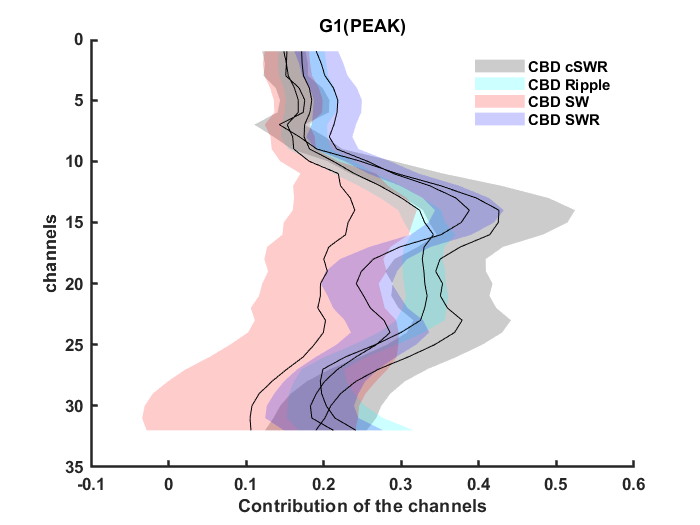



% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%............................
%G1-VEH
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_VEH_CSWR(:,1),timevect,  Sem_VEH_CSWR(:,1)' ,'g','alpha', ...
     Average_VEH_Ripple(:,1),timevect,Sem_VEH_Ripple(:,1)','m','alpha',...
     Average_VEH_SW(:,1),timevect,    Sem_VEH_SW(:,1)','y','alpha',  ...
     Average_VEH_SWR(:,1),timevect,   Sem_VEH_SWR(:,1)','b','alpha', 'orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


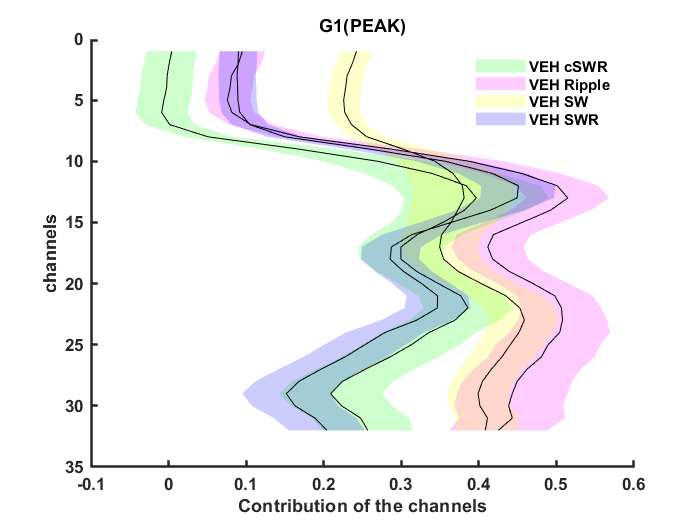


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%.........................
%G2-CBD
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,2),timevect,  Sem_CBD_CSWR(:,2)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,2),timevect,Sem_CBD_Ripple(:,2)','c','alpha', ...
     Average_CBD_SW(:,2),timevect,    Sem_CBD_SW(:,2)','r','alpha',  ...
     Average_CBD_SWR(:,2),timevect,   Sem_CBD_SWR(:,2)','b','alpha','orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


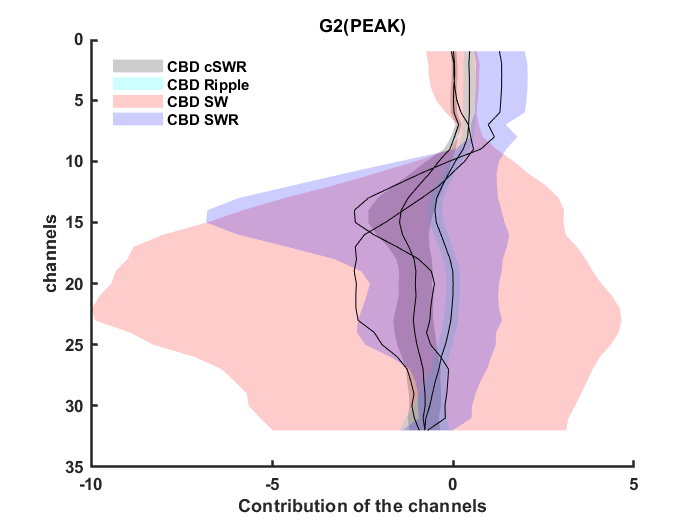



% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%...........
%G2-VEH
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_VEH_CSWR(:,2),timevect,  Sem_VEH_CSWR(:,2)' ,'g','alpha', ...
     Average_VEH_Ripple(:,2),timevect,Sem_VEH_Ripple(:,2)','m','alpha',...
     Average_VEH_SW(:,2),timevect,    Sem_VEH_SW(:,2)','y','alpha',  ...
     Average_VEH_SWR(:,2),timevect,   Sem_VEH_SWR(:,2)','b','alpha', 'orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


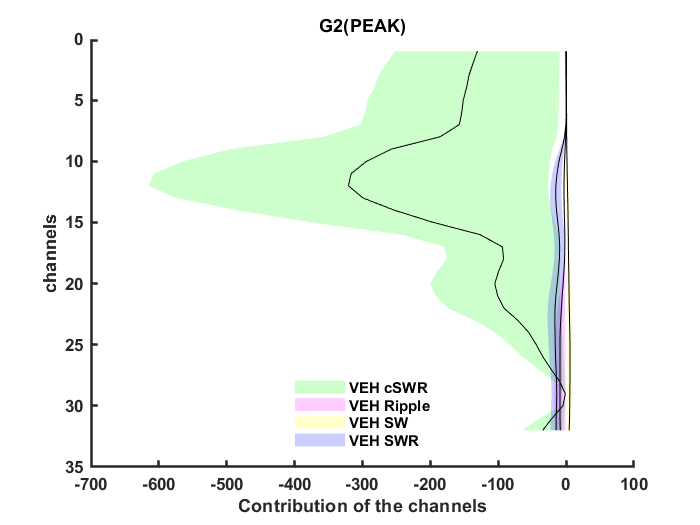


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

# Average of all conditions (CBD&VEH)

Mean_all_condi_CBD= mean(cat(3,Average_CBD_CSWR,Average_CBD_Ripple,Average_CBD_SW,Average_CBD_SWR),3)

Mean_all_condi_CBD =     0.1658    0.4276
    0.1682    0.4623
    0.1702    0.4668
    0.1811    0.4674
    0.1864    0.4736
    0.1850    0.4983
    0.1710    0.4958
    0.1776    0.5193
    0.1878    0.3836
    0.2245   -0.0270


Mean_all_condi_VEH=mean(cat(3,Average_VEH_CSWR,Average_VEH_Ripple,Average_VEH_SW,Average_VEH_SWR),3)

Mean_all_condi_VEH =     0.1079  -32.6359
    0.1044  -34.2058
    0.0994  -35.6629
    0.0985  -36.5060
    0.0962  -37.6435
    0.0979  -38.2107
    0.1120  -39.2796
    0.1562  -46.9601
    0.2539  -65.9885
    0.3393  -76.4063



Sem_all_condi_CBD = squeeze(std(cat(3,Average_CBD_CSWR,Average_CBD_Ripple,Average_CBD_SW,Average_CBD_SWR),0, 3) / sqrt(4));
Sem_all_condi_VEH = squeeze(std(cat(3,Average_VEH_CSWR,Average_VEH_Ripple,Average_VEH_SW,Average_VEH_SWR),0, 3) / sqrt(4));

%plot
%G1
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Mean_all_condi_CBD(:,1),timevect,Sem_all_condi_CBD(:,1),'g','alpha',...
    Mean_all_condi_VEH(:,1),timevect,Sem_all_condi_VEH(:,1),'k','alpha','orientation', 'horiz')

hl_g2 =   2×1 Line array:

  Line
  Line


hp_g2 =   2×1 Patch array:

  Patch
  Patch


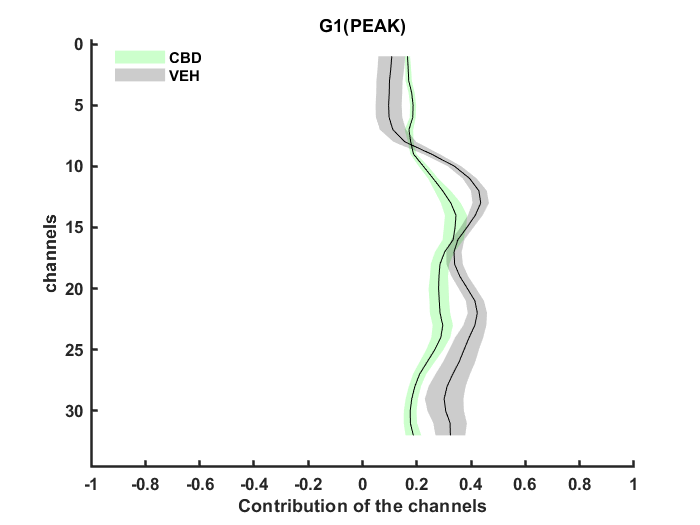

% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);
legend(hl_g2,'CBD','VEH','Location','best')
legend(hp_g2,'CBD','VEH','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([-10 10])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%G2
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Mean_all_condi_CBD(:,2),timevect,Sem_all_condi_CBD(:,2),'g','alpha',...
    Mean_all_condi_VEH(:,2),timevect,Sem_all_condi_VEH(:,2),'k','alpha','orientation', 'horiz')

hl_g2 =   2×1 Line array:

  Line
  Line


hp_g2 =   2×1 Patch array:

  Patch
  Patch


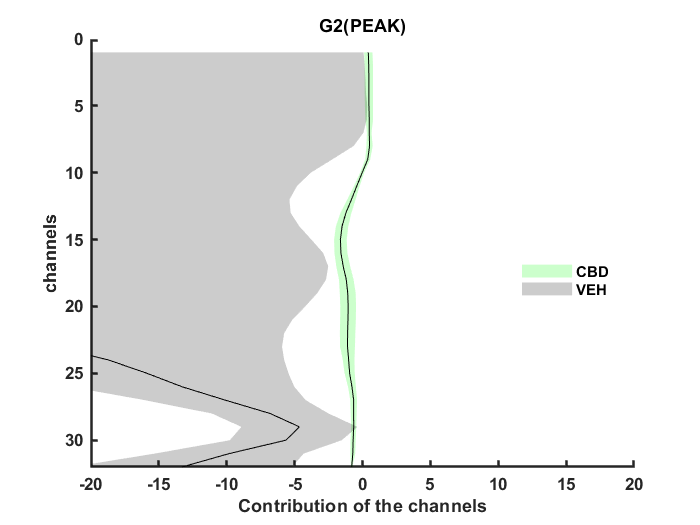

% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);
legend(hl_g2,'CBD','VEH','Location','best')
legend(hp_g2,'CBD','VEH','Location','best')
legend boxoff
xlabel('Contribution of the channels')
ylim([0 32])
xlim([-20 20])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

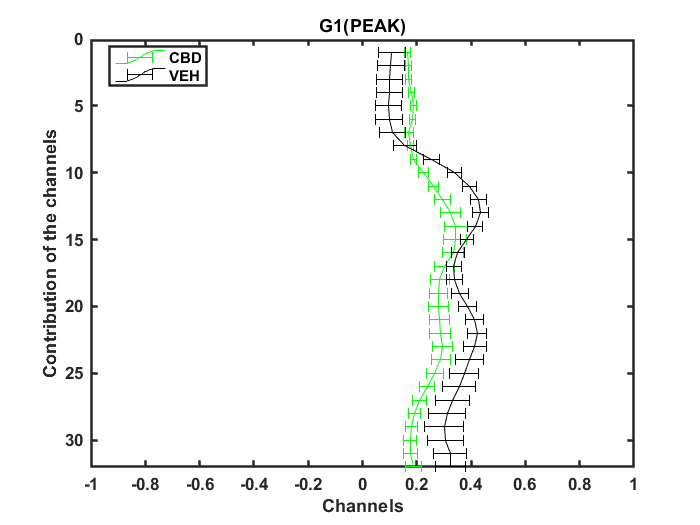

%.........................
%Errorbars
%G1
figure;

errorbar( Mean_all_condi_CBD(:,1),timevect, Sem_all_condi_CBD(:,1),'horizontal', 'g','LineWidth', 0.5);
hold on;
errorbar( Mean_all_condi_VEH(:,1),timevect, Sem_all_condi_VEH(:,1),'horizontal', 'k','LineWidth', 0.5);


legend('CBD','VEH','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-1 1])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

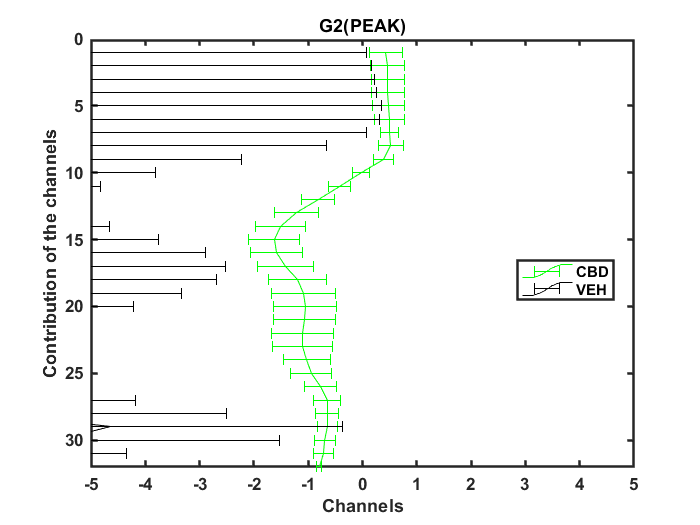

%G2
figure;

errorbar( Mean_all_condi_CBD(:,2),timevect, Sem_all_condi_CBD(:,2),'horizontal', 'g','LineWidth', 0.5);
hold on;
errorbar( Mean_all_condi_VEH(:,2),timevect, Sem_all_condi_VEH(:,2),'horizontal', 'k','LineWidth', 0.5);


legend('CBD','VEH','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-5 5])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(PEAK)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')